# Aula 11 - Margens


$$G(s)=\frac{K}{s(s+1)(2s+1)$$


## a) Calcule as margens de estabilidade para o sistema abaixo para K=1

clear
s=tf([1 0],1);
G=1/(s*(s+1)*(2*s+1))

G =
 
          1
  -----------------
  2 s^3 + 3 s^2 + s
 
Continuous-time transfer function.



syms omega
Gjw=1/expand((j*omega*(j*omega+1)*(2*j*omega+1)))

$$Gjw = -\frac{1}{2\,\omega^{3}\,\mathrm{i}+3\,\omega^{2}-\omega \,\mathrm{i}}$$

### Margem de Ganho

A margem de ganho é o ganho na frequência na qual a fase é -180º, ou seja, a parte imaginária do denominador de $G(j\omega)$ é nula, $2\omega^3-\omega=0$

wc_mg=solve(2*omega^3-omega,omega)

$$wc\_mg = \left(\begin{array}{c} 0\\ -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

Pegando apenas o valor de $\omega$ positivo e diferende de zero.

wc_mg=wc_mg(3)

$$wc\_mg = \frac{\sqrt{2}}{2}$$

Para essa frequencia de corte, o módulo de G é

modulo=abs(1/(j*wc_mg*(j*wc_mg+1)*(2*j*wc_mg+1)))

$$modulo = \frac{2}{3}$$


$$MG=\frac{1}{|G(j\omega)|}$$


MG=1/modulo

$$MG = \frac{3}{2}$$


$$MG_{dB}=20log(MG)$$


MGdb=20*log10(MG)

$$MGdb = \frac{20\,\log\left(\frac{3}{2}\right)}{\log\left(10\right)}$$

MGdb=double(MGdb)

MGdb = 3.5218

### Margem de Fase

A margem de fase é a distância entre a fase na frequência em que $|G(j\omega)|=1$ (ou $|G(j\omega)|_{dB}=0$) e -180º, ou seja, 180º mais essa fase.


$$|G(j\omega)|=\frac{1}{\sqrt{(3\omega^2)^2+(2\omega^3-\omega)^2}}=1$$


expand((3*omega^2)^2+(2*omega^3-omega)^2)

$$ans = 4\,\omega^{6}+5\,\omega^{4}+\omega^{2}$$


$$4\omega^6+0\omega^5+5\omega^4+0\omega^3+\omega^2+0\omega-1=0$$


pol=[4,0,5,0,1,0,-1];
wc_mf=roots(pol)

wc_mf =    0.2078 + 0.9119i
   0.2078 - 0.9119i
  -0.2078 + 0.9119i
  -0.2078 - 0.9119i
  -0.5716 + 0.0000i
   0.5716 + 0.0000i


pegando a única solução positiva e real

wc_mf=wc_mf(6)

wc_mf = 0.5716

fase=rad2deg(angle(1/(j*wc_mf*(j*wc_mf+1)*(2*j*wc_mf+1))))

fase = -168.5750

MF=fase+180

MF = 11.4250


$$MF=11,42º$$


### Verificando com o comando *margin*

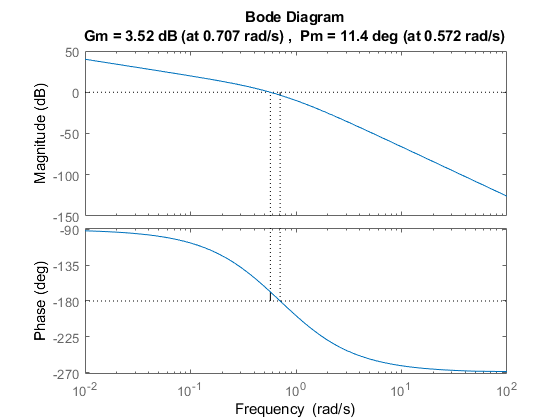

margin(G)

## b) Obtenha o valor de K que garanta MG > 6dB e MF>40deg. Simule a resposta em malha fechada.


$$G(s)=\frac{K}{s(s+1)(2s+1)}=\frac{K}{2\,s^3 +3\,s^2 +s}$$


**Para a Margem de Ganho:**

Se $MG_{dB}=6dB$

MG=10^(6/20)

MG = 1.9953

$MG=1.9953=\frac{1}{|G_{MF}(j\omega)|}$, para $\angle G_{MF}(j\omega)=-180º$

modulo=1/MG

modulo = 0.5012

fazendo $s=j\omega$

syms K
Gmf_jw=K/(2*(j*omega)^3+3*(j*omega)^2+(j*omega))

$$Gmf\_jw = -\frac{K}{2\,\omega^{3}\,\mathrm{i}+3\,\omega^{2}-\omega \,\mathrm{i}}$$

$\angle G_{MF}(j\omega)=-180º$, $G_{MF}(j\omega)$ é real, ou seja, $-2\omega^3+\omega=0$

wc_mg=solve(-2*omega^3+omega,omega)

$$wc\_mg = \left(\begin{array}{c} 0\\ -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

wc_mg=double(wc_mg(3))

wc_mg = 0.7071

$|G_{MF}(j\omega)|=\frac{K}{\sqrt{(-3\omega^2)^2+(-2\omega^3+\omega)^2}}$, porém sabemos que $-2\omega^3+\omega=0$.

Então $|G_{MF}(j\omega)|=\frac{K}{\sqrt{(-3\omega^2)^2}}=\frac{K}{3\omega^2}$

syms K
Kmg=modulo*3*wc_mg^2

Kmg = 0.7518

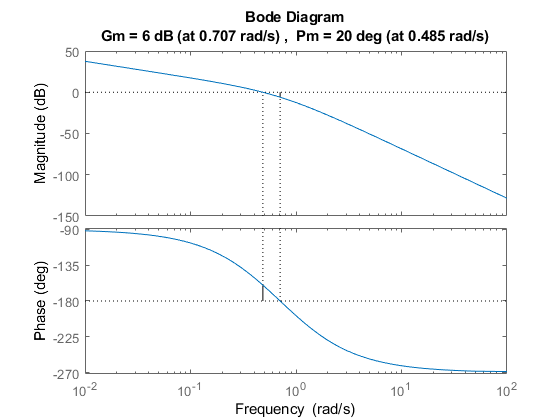

margin(Kmg*G)

Não atende ainda o critério da margem de fase.

**Para a Margem de fase:**


$$G(j\omega)=\frac{K}{-2\,\omega^3 \,\mathrm{i}-3\,\omega^2 +\omega \,\mathrm{i}}=\frac{K}{-3\omega^2+j(\omega-2\omega^3)}=\frac{K(-3\omega^2-j(\omega-2\omega^3))}{9\omega^4+j(\omega-2\omega^3)^2}$$



$$\angle{G_{MF}(j\omega)}=tg^{-1}\frac{2\omega^3-\omega}{-3\omega^2}$$
 

Para $MF=40º$ queremos $180+\angle{G_{MF}(j\omega)}=40º$, então $\angle{G_{MF}(j\omega)}=-140º$

$\angle{G_{MF}(j\omega)}=tg^{-1}tg^{-1}\frac{2\omega^3-\omega}{-3\omega^2}=-140º$         (1)

fase=-140;

Além disso, sabemos que na freqência de corte da margem de fase $|G_{MF}(j\omega)|=1$.

$|G_{MF}(j\omega)|=\frac{K}{\sqrt{(-3\omega^2)^2+(-2\omega^3+\omega)^2}}=1$   (2)

de (1) e (2) temos que:

syms K wc_mf
[Kmf, wc_mf]=vpasolve([(2*wc_mf^3-wc_mf)/(-3*wc_mf^2)==tand(fase),K==sqrt((-3*wc_mf^2)^2+(-2*wc_mf^3+wc_mf)^2)],[K, wc_mf],[1,1])

$$Kmf = 0.39421843321728363993332398608761$$

$$wc\_mf = 0.31727424527327042133268995132187$$

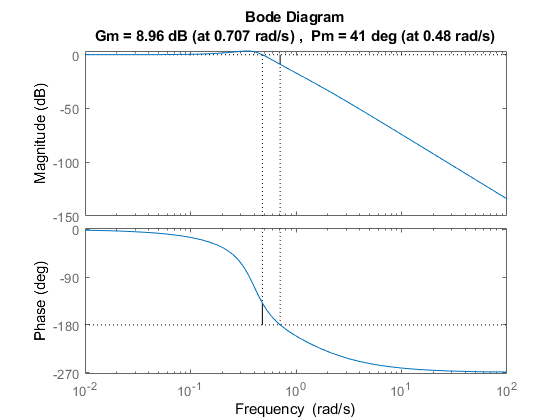

Kmf=double(Kmf);
margin(feedback(Kmf*G,1))

Como satisfaz os 2 requisitos, temos que $K\leq K_{MF}=0.39$.

## c) Por simulação numérica, faça um gráfico que relaciona o fator de amortecimento da resposta em malha fechada às margens de ganho e fase, demostrando que há uma relação direta do aumento das margens com o fator de amortecimento.

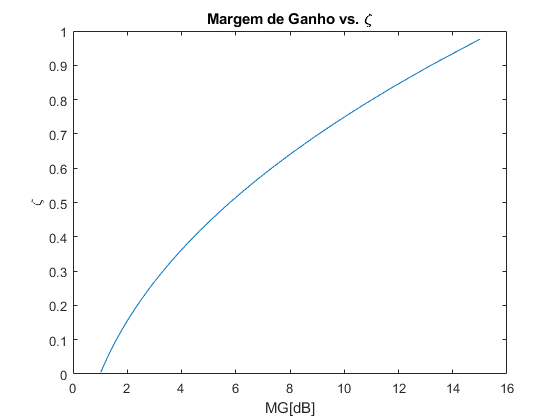

clear
K=linspace(0.1,1.46,100);
MF=zeros(1,length(K));
MG=zeros(1,length(K));
zeta=zeros(1,length(K));
for n=1:length(K)
    G=K(n)*tf(1,[2,3,1,0]);
    [wn,z,p] = damp(feedback(G,1));
    zeta(n)=z(1);
    [MG(n),MF(n)] = margin(G);
end
plot(MG,zeta)
title("Margem de Ganho vs. \zeta")
ylabel('\zeta')
xlabel('MG[dB]')

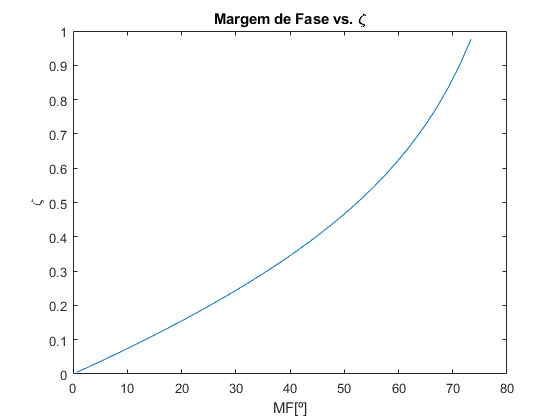

plot(MF,zeta)
title("Margem de Fase vs. \zeta")
ylabel('\zeta')
xlabel('MF[º]')